clear all
close all
clc

Simsize para ditar o numero de valores que vamos coletar

simsize=20;

# Simulação do sistema criogenico EMA - C

O objetivo é simular a temperatura obtida para direfentes valores de $R_1$(R1) e $R_2$ (R2) onde se obtem valores aceitaveis de temperatura na amostra (sample)

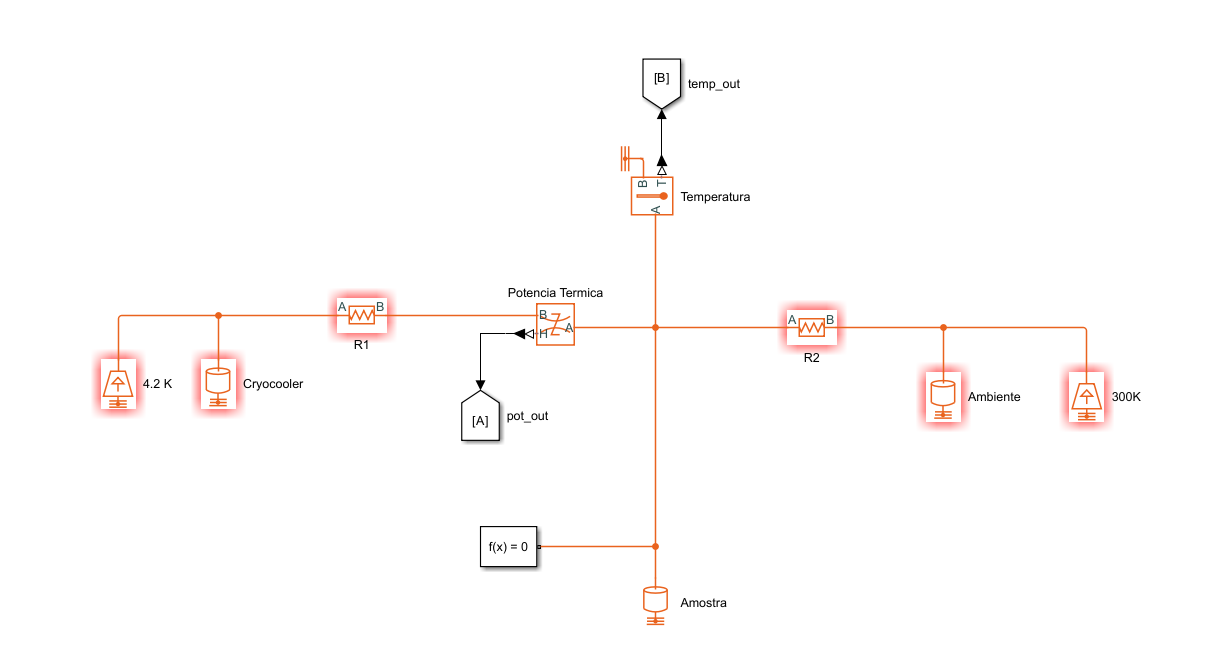

Estabelecendo os valores de $R_1$ e $R_2$

r1=logspace(-3,1,simsize);
% r2max = 300;
% r2min = 10;
r2=logspace(0,log10(300),simsize);

Tempo de simulação

%tsim = [0 1000000];

simIn = Simulink.SimulationInput("Testeotimiz2");

set_param("Testeotimiz2",'FastRestart','on');

simIn = setModelParameter(simIn,"TimeOut",1e+6);

Alocar as matrizes de resultado

temperature = zeros(length(r1),length(r2));
power = zeros(length(r1),length(r2));

Para fazer um teste preeliminar, e conferir se a simulação esta atribuindo valores corretos, primeiro selecionamos as resistencias

r1_r=r1(20)

r1_r = 10

r2_r=r2(20)

r2_r = 300.0000

Temperaturas das extremidades

Cold_T =  4.2;
Hot_T =  300;

if Cold_T == 4.2
    C_s = '4';
else
    C_s = num2str(Cold_T,3);
end

H_s = num2str(Hot_T,3);

Outras constantes que vamos precisar

%calores especificos
sh_sample = 0.42;
%sh_envsup = steel304SH no modelworkspace, inicializada em T=300K
%sh_coldfing = CuRRR50SH no modelworkspace, inicializada em T=4K

%massas [kg]
m_sample = 0.9;
m_envsup = 100;
m_coldfing = 0.9;


E rodamos a simulação

simOut=sim(simIn);
T_end = simOut.temp_out(1,1,end)

T_end = 13.7419

P_end = simOut.pot_out(1,1,end)

P_end = 0.9542

Marcação de tempo de rodagem do codigo

t1 = datetime('now');

for i=1:length(r1)
    r1_r=r1(i);
    for j=1:length(r2)
        r2_r=r2(j);
        simOut=sim(simIn);
        temperature(i,j)=simOut.temp_out(1,1,end);
        power(i,j) = simOut.pot_out(1,1,end);
    end
end

diff([datetime('now') t1])

ans = duration
   -00:03:13


writematrix(temperature,strcat(C_s,'K-',H_s,'K-Temperature.txt'),"FileType","auto");
writematrix(temperature,strcat(C_s,'K-',H_s,'K-Power.txt'),"FileType","auto");

view_vec = [-120 30 ];

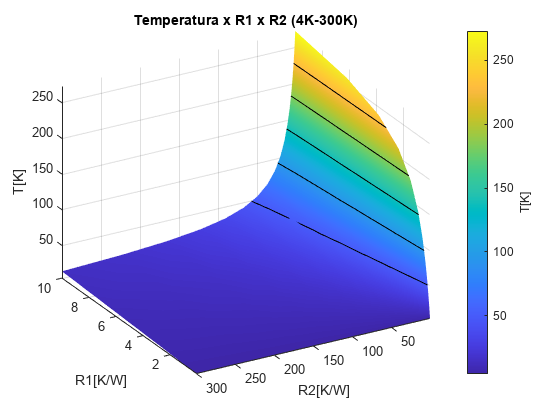

temp = surf(r1,r2,temperature.','EdgeColor','none','FaceColor','interp');
xlabel('R1[K/W]')
ylabel('R2[K/W]')
zlabel('T[K]')
head_T = strcat('Temperatura x R1 x R2 (',C_s,'K-',H_s,'K)');
title(head_T)
c1=colorbar;
c1.Label.String = 'T[K]';
view(view_vec)
hold on;
contour3(r1,r2,temperature.',5,'k');
name = strcat(C_s,'-to-',H_s,' temp.png');
saveas(gcf, name,'png')

figure;

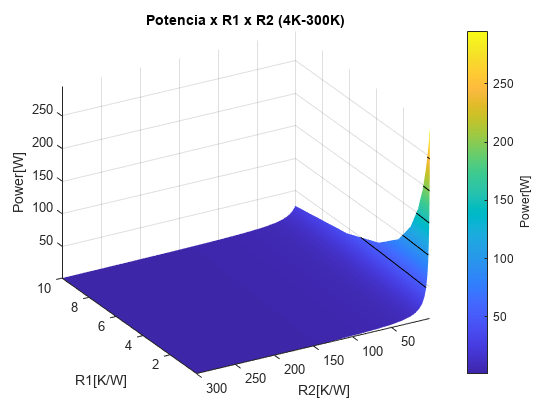

powe = surf(r1,r2,power.','EdgeColor','none','FaceColor','interp');
xlabel('R1[K/W]')
ylabel('R2[K/W]')
zlabel('Power[W]')
head_T = strcat('Potencia x R1 x R2 (',C_s,'K-',H_s,'K)');
title(head_T)
c2=colorbar;
c2.Label.String = 'Power[W]';
view(view_vec)
hold on;
contour3(r1,r2,power.',5,'k');
name = strcat(C_s,'-to-',H_s,' powe.png');
saveas(gcf, name,'png')

figure;

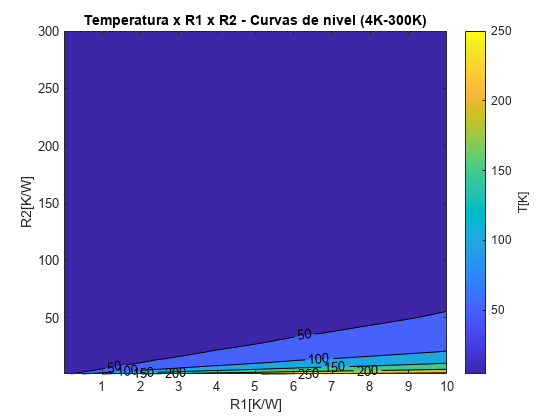

tempc = contourf(r1,r2,temperature.','ShowText','on');
xlabel('R1[K/W]')
ylabel('R2[K/W]')
head_T = strcat('Temperatura x R1 x R2 - Curvas de nivel (',C_s,'K-',H_s,'K)');
title(head_T)
c3 = colorbar;
c3.Label.String = 'T[K]';
name = strcat(C_s,'-to-',H_s,' tempc.png');
saveas(gcf, name,'png')

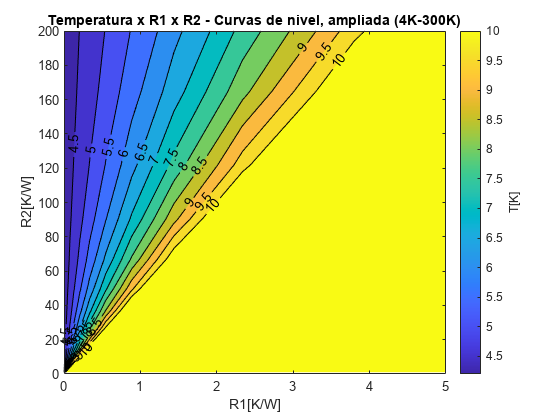

figure;
tempcz = contourf(r1,r2,temperature.',0:0.5:10,'ShowText','on');
xlabel('R1[K/W]')
ylabel('R2[K/W]')
head_T = strcat('Temperatura x R1 x R2 - Curvas de nivel, ampliada (',C_s,'K-',H_s,'K)');
title(head_T)
xlim([0 5])
ylim([0 200])
c3 = colorbar;
c3.Label.String = 'T[K]';
name = strcat(C_s,'-to-',H_s,' tempcz.png');
saveas(gcf, name,'png')

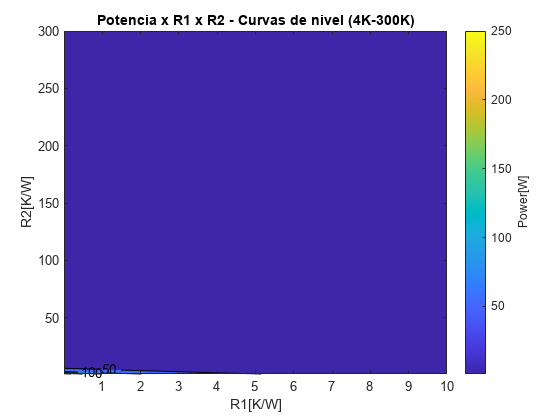

powec = contourf(r1,r2,power.','ShowText','on');
xlabel('R1[K/W]')
ylabel('R2[K/W]')
head_T = strcat('Potencia x R1 x R2 - Curvas de nivel (',C_s,'K-',H_s,'K)');
title(head_T)
c4 = colorbar;
c4.Label.String = 'Power[W]';
name = strcat(C_s,'-to-',H_s,' powec.png');
saveas(gcf, name,'png')

figure;

Zoom no ultimo grafico

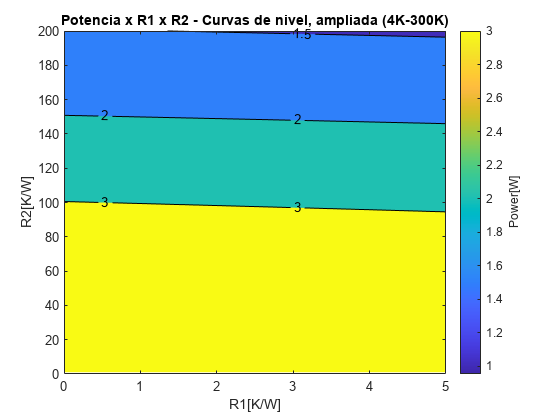

lvlvecp = 0:0.5:4;
powecz = contourf(r1,r2,power.',[0.1 0.2 0.3 0.5 1 1.5 2 3],'ShowText','on');
xlabel('R1[K/W]')
ylabel('R2[K/W]')
head_T = strcat('Potencia x R1 x R2 - Curvas de nivel, ampliada (',C_s,'K-',H_s,'K)');
title(head_T)
xlim([0 5])
ylim([0 200])
c4 = colorbar;
c4.Label.String = 'Power[W]';
name = strcat(C_s,'-to-',H_s,' powecz.png');
saveas(gcf, name,'png')

figure;

Alterar o modelo para o uso do fast Restart alterou muito os resultados por algum motivo,